**EPFL Spacecraft Team - CHESS Mission Design**

Arnaud Muller & Antoine Clout

Autumn 2020

clc
clear
close all

Read TUDAT propagation results

if (~exist('RAAN_Optimisation_Results')) %#ok<*EXIST>
    RAAN_Optimisation_Results= importdata('RAAN_Optimisation_Results.dat');
    RAANValues= importdata('RAAN_Optimisation_RAANValues.dat');
end
[nb_of_epochs,tmp]=size(RAAN_Optimisation_Results);
nb_RAAN=tmp-1;
clear tmp

Compute maximum eclipse duration for each spacecraft

maxEclipse=zeros(nb_RAAN,1);
for i=1:nb_RAAN
    compteur = 0;
    Eclipses = zeros(nb_of_epochs,1);
    for k=1:nb_of_epochs
        if RAAN_Optimisation_Results(k,i+1) == 0
            Eclipses(k) = compteur;
            compteur = 0;
        else
            compteur = compteur +1;
        end
    end
    if sum(Eclipses(end-1,1)==0)
        Eclipses(k) =0;
    else
        Eclipses(k) = compteur;
    end
    clear compteur
    Eclipses=Eclipses(Eclipses > 0);
    if isempty(max(Eclipses))
        maxEclipse(i)=0;
    else
        maxEclipse(i)=max(Eclipses);
    end
end

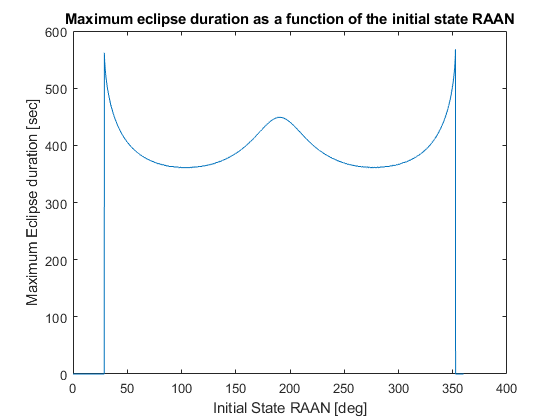

figure
plot(RAANValues,maxEclipse)
xlabel('Initial State RAAN [deg]')
ylabel('Maximum Eclipse duration [sec]')
title('Maximum eclipse duration as a function of the initial state RAAN')